clear,clc,close all
import_data_2025MCM_C
medalAmountForSports = readtable("Sport_medal_people2.xlsx");
people2028 = readtable("people2028.xlsx");

tic
never_medal_ind = zeros(3,1);
err_ind = zeros(2,1);
kmedal = 0;
kerr = 0;
knormal = 0;
ktolowevents1 = 0;
ktolowevents2 = 0;
sumallsportimportant1 = struct();
sumallsportimportant2 = struct();
firsttwosport = ["" "" ""; "" "" ""];
predicttable = table();
for n = 1:length(NOC2Country)
    country_temp = NOC2Country(n,1);
    data = medalAmountForSports(string(medalAmountForSports.NOC) == country_temp,:);
    m = max(data.BronzeCount);
    data.BronzeCount = data.BronzeCount/m;
    NumObs = height(data);
    % Reset the random stream state, for reproducibility
    % Comment this line out to generate different data partitions each time the example is run
    rng('default');
    if height(data)<=6
        ktolowevents1 = ktolowevents1 + 1;
        disp(NOC2Country(n,2) + '参加过的项目太少,1')
        continue
    end
    % try
        c = cvpartition(NumObs,'HoldOut',0.4);
        TrainingInd = training(c);
        TestInd = test(c);

        if all(isnan((data.BronzeCount)))
            kmedal = kmedal + 1;
            never_medal_ind(kmedal) = n;
            data.BronzeCount = zeros(height(data),1);
            % n
            continue
        end

        mdlTobit = fitLGDModel(data(TrainingInd,:),'tobit','CensoringSide','both','PredictorVars',{'sumofpeople' 'Year' 'Sport'},'ResponseVar','BronzeCount');
        
        dataBronzeCountPredicted = table;
        dataBronzeCountPredicted.Observed = data.BronzeCount(TestInd) * m;

        dataBronzeCountPredicted.Tobit = predict(mdlTobit,data(TestInd,:)) * m;
        % disp((dataBronzeCountPredicted))

        [~,ind] = sort(mdlTobit.UnderlyingModel.Coefficients.Estimate,'descend');
        % 
        % for m = 1:length(ind)
        %     mdlTobit.UnderlyingModel.CoefficientNames{ind(m)}
        % end
        
        % temp = []

        
        % 判断运动的重要性
        temp = mdlTobit.UnderlyingModel.CoefficientNames;
        if length(temp) <=5
            ktolowevents2 = 0;

            disp(NOC2Country(n,2) + '参加过的项目太少,2')
            continue
        end

        s = [string(temp{ind(1)}),string(temp{ind(2)})];
        indtemp = 2;
        for chachong = 1:4
        while contains("sumofpeople",s)
            for m_temp = 1:2
                if s(m_temp) == "sumofpeople"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("Year",s)
            for m_temp = 1:2
                if s(m_temp) == "Year"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("(Intercept)",s)
            for m_temp = 1:2
                if s(m_temp) == "(Intercept)"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("(Sigma)",s)
            for m_temp = 1:2
                if s(m_temp) == "(Sigma)"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        end
        
        knormal = knormal + 1;
        firsttwosport(knormal,:) = [NOC2Country(n,2) s];
        tc1 = char(s(1));
        tc1(tc1==' ') = '_';
        tc1(tc1=='/') = '_';
        tc1(tc1=='-') = '_';
        ts1 = string(tc1);

        tc2 = char(s(2));
        tc2(tc2==' ') = '_';
        tc2(tc2=='/') = '_';
        tc2(tc2=='-') = '_';
        ts2 = string(tc2);        
        if ismember(tc1,fieldnames(sumallsportimportant1))
            eval("sumallsportimportant1."+ts1+" =  sumallsportimportant1."+ts1+" + 1;");
        else
            eval("sumallsportimportant1."+ts1+" = 1;");
        end
        if ismember(tc2,fieldnames(sumallsportimportant2))
            eval("sumallsportimportant2."+ts2+" =  sumallsportimportant2."+ts2+" + 1;");
        else
            eval("sumallsportimportant2."+ts2+" = 1;");
        end

        %PREDICT 2028
        predict_2028 = people2028(people2028.NOC == country_temp,:);

        total = predict(mdlTobit,predict_2028) * m;
        total(isnan(total)) = 0;
        % sum(total)
        predicttable.NOC(knormal) = country_temp;
        predicttable.country(knormal) = NOC2Country(n,2);
        predicttable.BronzeCount(knormal) = sum(total);
        


    % catch ME
    %     kerr = kerr + 1;
    %     err_ind(kerr) = n;
    %     disp(['Iteration ', num2str(n), ': Failed with error - ', ME.message]);
    %     % 可以选择跳过当前迭代或执行其他错误处理逻辑
    % end
    % if mod(n,20) == 0
    %     n
    % end
end

North Yemen参加过的项目太少,1


South Yemen参加过的项目太少,1


Refugee Olympic Athletes参加过的项目太少,1


Crete参加过的项目太少,1


Rhodesia参加过的项目太少,1


Circus参加过的项目太少,1


North Borneo参加过的项目太少,1


Unknown参加过的项目太少,1
Newfoundland参加过的项目太少,1


South Sudan参加过的项目太少,1


% never_medal_ind
toc

历时 19.054423 秒。


firsttwosport

firsttwosport = 138×3 string 数组
    "China"            "Sport_Karate"            "Sport_Volleyball"      
    "Denmark"          "Sport_Table Tennis"      "Sport_Art Competitions"
    "Netherlands"      "Sport_Judo"              "Sport_Weightlifting"   
    "Finland"          "Sport_Wrestling"         "Sport_Gymnastics"      
    "Norway"           "Sport_Figure Skating"    "Sport_Shooting"        
    "Romania"          "Sport_Gymnastics"        "Sport_Boxing"          
    "Estonia"          "Sport_Judo"              "Sport_Sailing"         
    "France"           "Sport_Judo"              "Sport_Canoe"           
    "Morocco"          "Sport_Boxing"            "Sport_Athletics"       
    "Spain"            "Sport_Canoe"             "Sport_Tennis"          
    "Egypt"            "Sport_Taekwondo"         "Sport_Triathlon"       
    "Iran"             "Sport_Taekwondo"         "Sport_Weightlifting"   
    "Bulgaria"         "Sport_Taekwondo"         "Sport_Judo"            
    "I

predicttable

predicttable = 138×3 table
     NOC        country       BronzeCount
    _____    _____________    ___________

    "CHN"    "China"              31.256 
    "DEN"    "Denmark"            4.5178 
    "NED"    "Netherlands"         11.74 
    "FIN"    "Finland"            1.1643 
    "NOR"    "Norway"             1.8628 
    "ROU"    "Romania"            4.2791 
    "EST"    "Estonia"         0.0067261 
    "FRA"    "France"             15.814 
    "MAR"    "Morocco"            1.0441 
    "ESP"    "Spain"              8.5701 
    "EGY"    "Egypt"                   0 
    "IRI"    "Iran"               1.6205 
    "BUL"    "Bulgaria"           4.9462 
    "ITA"    "Italy"              23.195 
    "AZE"    "Azerbaijan"         7.4586 
    "RUS"    "Russia"             27.205 


% disp((dataBronzeCountPredicted))

sumallsportimportant1

sumallsportimportant1 = 包含以下字段的 struct :
               Sport_Karate: 7
         Sport_Table_Tennis: 2
                 Sport_Judo: 11
            Sport_Wrestling: 12
       Sport_Figure_Skating: 1
           Sport_Gymnastics: 4
               Sport_Boxing: 20
                Sport_Canoe: 9
            Sport_Taekwondo: 8
           Sport_Volleyball: 5
        Sport_Weightlifting: 8
                 Sport_Golf: 2
                 Sport_Polo: 1
              Sport_Cycling: 4
             Sport_Shooting: 5
            Sport_Badminton: 4
             Sport_Football: 3
            Sport_Athletics: 13
         Sport_Trampolining: 1
     Sport_Art_Competitions: 3
                Sport_Rugby: 2
              Sport_Sailing: 2
           Sport_Basketball: 3
         Sport_Jeu_De_Paume: 1
              Sport_Fencing: 1
    Sport_Modern_Pentathlon: 1
              Sport_Archery: 2
               Sport_Tennis: 1
       Sport_Sport_Climbing: 1
           Sport_Equestrian: 1


sumallsportimportant2

sumallsportimportant2 = 包含以下字段的 struct :
               Sport_Volleyball: 6
         Sport_Art_Competitions: 2
            Sport_Weightlifting: 7
               Sport_Gymnastics: 7
                 Sport_Shooting: 3
                   Sport_Boxing: 15
                  Sport_Sailing: 3
                    Sport_Canoe: 9
                Sport_Athletics: 11
                   Sport_Tennis: 4
                Sport_Triathlon: 4
                     Sport_Judo: 12
                   Sport_Karate: 3
                Sport_Wrestling: 7
                Sport_Taekwondo: 10
            Sport_Skateboarding: 2
                 Sport_Handball: 2
                  Sport_Archery: 3
                   Sport_Rowing: 3
                 Sport_Football: 3
                  Sport_Surfing: 1
                  Sport_Cycling: 5
                  Sport_Fencing: 4
               Sport_Tug_Of_War: 1
                Sport_Badminton: 3
           Sport_Figure_Skating: 1
                     Sport_Polo: 1
          



% people2028.Year = 2028 * ones(height(people2028),1)
% dataBronzeCountPredicted.Tobit = predict(mdlTobit,data(TestInd,:)); %%%预测用！！！

[~,ind] = sort(predicttable.BronzeCount,'descend');
predicttable = predicttable(ind,:)

predicttable = 138×3 table
     NOC         country        BronzeCount
    _____    _______________    ___________

    "GDR"    "East Germany"       108.15   
    "URS"    "Soviet Union"       50.191   
    "USA"    "United States"      43.662   
    "FRG"    "West Germany"       43.224   
    "CHN"    "China"              31.256   
    "RUS"    "Russia"             27.205   
    "JPN"    "Japan"              23.259   
    "ITA"    "Italy"              23.195   
    "AUS"    "Australia"          18.762   
    "GER"    "Germany"            18.502   
    "FRA"    "France"             15.814   
    "GBR"    "Great Britain"      14.579   
    "PRK"    "North Korea"        14.097   
    "EUN"    "Unified Team"       12.981   
    "BRA"    "Brazil"              12.11   
    "NED"    "Netherlands"         11.74   


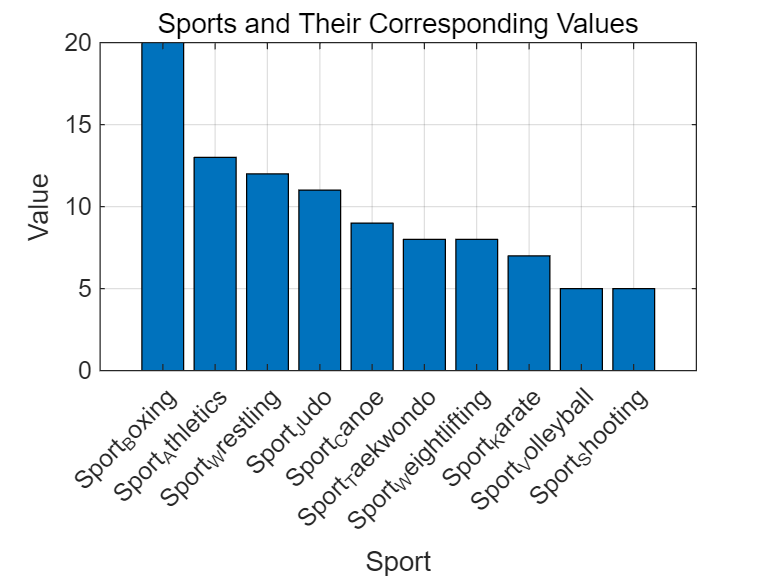

% % ind_change = [1 2 5 14 22 85 112 117 139]
% % 
% % 
% % % predicttable(1:155~=ind_change,:)
% % predicttable([3,4,6:13],:)
% 
% % 假设你的结构体名为 sumallsportimportant1
% sports = string(fieldnames(sumallsportimportant1)); % 获取结构体字段名（运动项目）
% values = struct2array(sumallsportimportant1); % 将结构体转换为数组（对应的数值）
% [values,ind] = sort(values,'descend');
% sports = sports(ind(1:10));
% values = values(1:10);
% % 注意：struct2array 默认返回结构体中第一个字段的数组，如果所有字段都是相同大小的数值数组，这可以工作。
% % 但如果结构体中有非数值字段或字段大小不一致，这种方法会出错。
% % 在这个例子中，我们假设所有字段都是数值且大小相同（即只有一个数值）。
% 
% % 如果 struct2array 不适用（例如，如果结构体中有混合类型的数据），你需要手动提取数值：
% % values = zeros(1, length(sports));
% % for i = 1:length(sports)
% %     values(i) = sumallsportimportant1.(sports{i});
% % end
% 
% % 绘制条形图
% figure; % 创建新图形窗口
% bar(values); % 绘制条形图（默认 x 轴是索引）
% 
% % 设置 x 轴标签为运动项目名称
% set(gca, 'XTickLabel', sports); % gca 获取当前轴句柄
% % xstickrotation(45); % 旋转 x 轴标签，以便更好地显示长名称
%  xtickangle(45);
% % 设置图表标题和轴标签
% title('Sports and Their Corresponding Values');
% xlabel('Sport');
% ylabel('Value');
% 
% % 如果需要，还可以添加网格线、图例等
% grid on;

% % 假设你的结构体名为 sumallsportimportant1
% sports = string(fieldnames(sumallsportimportant2)); % 获取结构体字段名（运动项目）
% values = struct2array(sumallsportimportant2); % 将结构体转换为数组（对应的数值）
% [values,ind] = sort(values,'descend');
% sports = sports(ind(1:10));
% values = values(1:10);
% 
% % 注意：struct2array 默认返回结构体中第一个字段的数组，如果所有字段都是相同大小的数值数组，这可以工作。
% % 但如果结构体中有非数值字段或字段大小不一致，这种方法会出错。
% % 在这个例子中，我们假设所有字段都是数值且大小相同（即只有一个数值）。
% 
% % 如果 struct2array 不适用（例如，如果结构体中有混合类型的数据），你需要手动提取数值：
% % values = zeros(1, length(sports));
% % for i = 1:length(sports)
% %     values(i) = sumallsportimportant1.(sports{i});
% % end
% 
% % 绘制条形图
% figure; % 创建新图形窗口
% bar(values); % 绘制条形图（默认 x 轴是索引）
% 
% % 设置 x 轴标签为运动项目名称
% set(gca, 'XTickLabel', sports); % gca 获取当前轴句柄
% % xstickrotation(45); % 旋转 x 轴标签，以便更好地显示长名称
%  xtickangle(45);
% % 设置图表标题和轴标签
% title('Sports and Their Corresponding Values');
% xlabel('Sport');
% ylabel('Value');
% 
% % 如果需要，还可以添加网格线、图例等
% grid on;